clearvars; clc;

# Esercitazione 6

#### Definitions

A=[0 1;0 -1];
B=[0;1];
C=[1 0];
D=0;

Ts=0.05;

r=1;

sys=ss(A,B,C,D);
sys_x=ss(A,B,eye(2),0);

#### Discretize the model

sys_dt=c2d(sys,Ts,'zoh');
[Ad,Bd,Cd,Dd]=ssdata(sys_dt);

#### Set design parameters for MPCtools

Cy=eye(2);
Cz=Cd; Dz=0;
Cc=Cd; Dc=0;

Q=1000;
R=1;

cmode=0;
h=Ts;
z_max=inf;
z_min=-inf;
u_max=1;
u_min=-1;
du_max=inf;
du_min=-inf;

Hp=100;
Hu=100;
Hw=1;
z_blk=1;
u_blk=1;

md=MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk,Hu,u_blk,du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h,cmode,'qp_as');

Setting up matrices...
Preparing matrix setup...
Building prediction matrices...
Post-creation matrix operations...


#### Simulation

t_sim=3;
rho=1;
out=sim('sim_esercitazione_6.slx');

Update start, t=0.00
Update start, t=0.05
Update start, t=0.10
Update start, t=0.15
Update start, t=0.20
Update start, t=0.25
Update start, t=0.30
Update start, t=0.35
Update start, t=0.40
Update start, t=0.45
Update start, t=0.50
Update start, t=0.55
Update start, t=0.60
Update start, t=0.65
Update start, t=0.70
Update start, t=0.75
Update start, t=0.80
Update start, t=0.85
Update start, t=0.90
Update start, t=0.95
Update start, t=1.00
Update start, t=1.05
Update start, t=1.10
Update start, t=1.15
Update start, t=1.20
Update start, t=1.25
Update start, t=1.30
Update start, t=1.35
Update start, t=1.40
Update start, t=1.45
Update start, t=1.50
Update start, t=1.55
Update start, t=1.60
Update start, t=1.65
Update start, t=1.70
Update start, t=1.75
Update start, t=1.80
Update start, t=1.85
Update start, t=1.90
Update start, t=1.95
Update start, t=2.00
Update start, t=2.05
Update start, t=2.10
Update start, t=2.15
Update start, t=2.20
Update start, t=2.25
Update start, t=2.30
Update start,

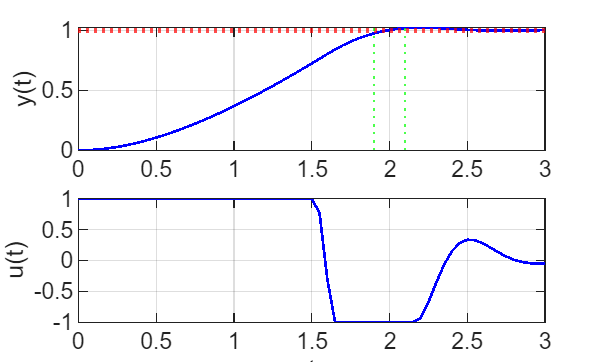

figure;
subplot(211), plot(out.y.time,out.y.data,'b','LineWidth',1.0);
yline(1.01,':r','LineWidth',1.0),
yline(0.99,':r','LineWidth',1.0),
xline(2*1.05,':g','LineWidth',1.0),
xline(2*0.95,':g','LineWidth',1.0),
hold on, grid on, ylabel('y(t)');

subplot(212), plot(out.u.time,out.u.data,'b','LineWidth',1.0),
hold on, grid on, ylabel('u(t)'), xlabel('t');